clear all
p = parselog('C:\Users\Tomaso\Desktop\flight_data_VSQP\17_24_32\17_24_32\80_01_09__03_22_34_SD.data');
addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))

data = p.aircrafts.data.EFF_FULL_INDI;
act = cellfun(@(S) sscanf(S, '%f,').', data.u, 'Uniform', 0);
act = cell2mat(act);

thrust_quad = sum(act(:,1:4),2);
sf = get_sf(data.timestamp);
f_filter = 5;
order = 4;

f = figure(1);
clf
tiledlayout(5,3,'TileSpacing','compact','Padding','tight')

ax1=nexttile([1 2]);
plot(data.timestamp,low_butter(thrust_quad/4,f_filter,sf,0,order))
hold on
ylim([1000,2000]);
grid on
grid minor
title("Thrust of Quad [pwm]")
lgd=legend('Actual');
lgd.Layout.Tile = 3;
hold off
nexttile

ax2=nexttile([1 2]);
plot(data.timestamp,low_butter(data.theta_alt,f_filter,sf,0,order))
hold on
plot(data.timestamp,low_butter(data.theta_ref_alt,f_filter,sf,0,order))
grid on
grid minor
yline([-3,10],'--',{'min','max'})
title("Theta [deg]")
lgd=legend('Actual','Reference');
lgd.Layout.Tile = 6;
ylim([-6 14]);
hold off
nexttile

ax3=nexttile([1 2]);
plot(data.timestamp,data.wing_angle_deg)
ylim([-10 110]);
hold on
yline([0 80],'--',{'Quad-Mode','FWD-Mode'})
grid on
grid minor
title("Skew Angle [deg]")
hold off
nexttile

ax4=nexttile([1 2]);
plot(data.timestamp,-1*data.position_D)
hold on
plot(data.timestamp,-1*data.position_D_ref)
title("Vertical position [m]")
ylim([0,6])
grid on
grid minor
hold off
nexttile
lgd=legend('Actual','Reference');

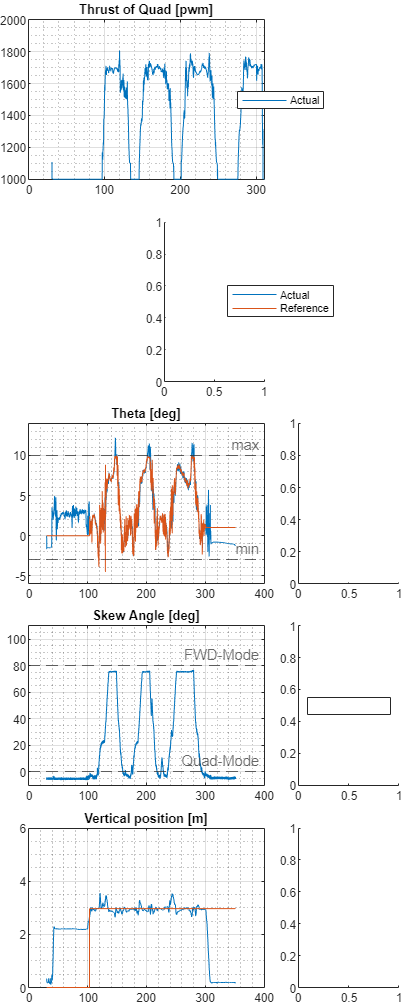

lgd.Layout.Tile = 12;


ax5=nexttile([1 3]);

Error using nexttile
The layout does not have sufficient space.

plot(data.timestamp,low_butter(data.airspeed,f_filter,sf,0,order))
title("Airspeed [m/s]")
ylim([0,20]);
%linkaxes([ax1,ax2,ax3,ax4,ax5],'x');
xlim([230 290]);
xlabel("Time [s]")
grid on
grid minor
hold off
nexttile

f.Units = 'inches';
f.OuterPosition = [0.25 0.25 6 15];